**Load in the image**

filePath = '/Users/elizabeth 1/Desktop/Wu Lab/6. clonogenic assay by EB copy/subimages retaken';
cd (filePath);
fileList = dir(fullfile(filePath, '*.jpeg'));  % List all PNG files (modify the extension as needed)

% Extract the filenames from the structure
filenames = {fileList.name}

filenames = 1×4 cell array
    {'RCC4_Fluva_1.25+VHLa.jpeg'}    {'RCC4_Fluva_1.25+VHLb.jpeg'}    {'RCC4_Fluva_1.25c.jpeg'}    {'RCC4_Fluva_1.25d.jpeg'}


photoNumber = length(filenames);
%allow user to use slider to iterate through images in the specified folder
%(don't have to type in image neame each time)
i =1;
imgTitle = string(filenames(i))

imgTitle = "RCC4_Fluva_1.25+VHLa.jpeg"

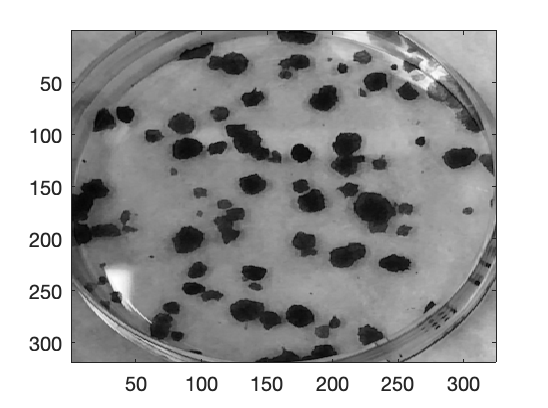

img1 = imread(imgTitle); %read in image
img = rgb2gray(img1); %convert to grayscale
img_blurred = imgaussfilt(img);
imagesc(img_blurred), colormap gray

**crop the image**

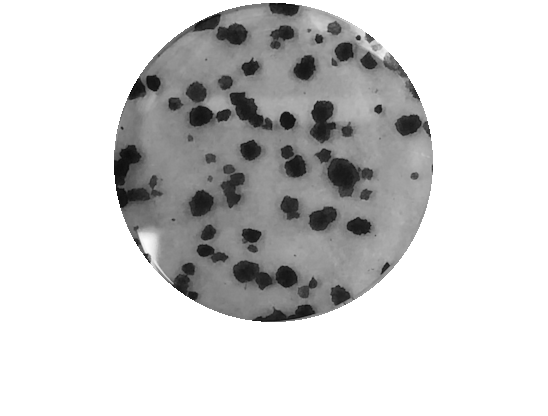

%cut out the center region representing the cells in the dish

% Get the size of the image
[rows, cols] = size(img_blurred);

% Calculate the radius of the circular region
radius = min(rows, cols) / 2;

% Calculate the center coordinates of the circular region
centerX = round(cols / 2);
centerY = round(rows / 2);

% Create a meshgrid of coordinates
[X, Y] = meshgrid(1:cols, 1:rows);

% Calculate the distance of each point from the center
distances = sqrt((X - centerX).^2 + (Y - centerY).^2);

% Create a logical mask where the values inside the circle are set to true (1)
mask = distances <= radius;

% Create a white background image
background = ones(size(img_blurred), 'like', img_blurred) * 255;

% Apply the mask to the background
img_cropped = img_blurred .* uint8(mask) + background .* uint8(~mask);

% Display the cropped image
imshow(img_cropped);

Binarize

- threshold **115** for `"7860_Fluva1.25+VHLa.jpeg"`

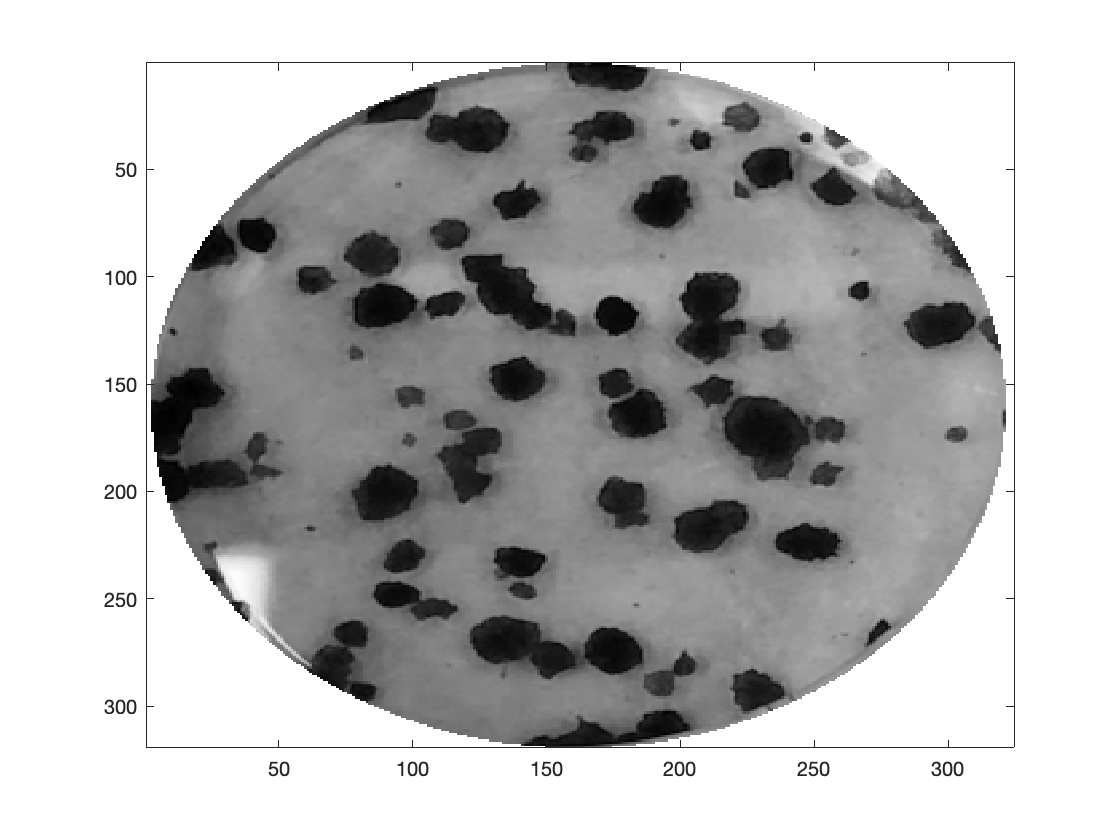

%threshold using variance:      
% Define the window sizes for variance calculation
        windowSizes = [3, 5, 7, 9];
        
        % Initialize a mask to store the blurry regions
        blurryMask = false(size(img_cropped));
        
        % Calculate variance at different window sizes
        for i = 1:numel(windowSizes)
            windowSize = windowSizes(i);
            
            % Calculate the local variance using imfilter and imgaussfilt
                localVariance = imfilter(double(img_cropped).^2, ones(windowSize)/windowSize^2, 'replicate') - imgaussfilt(double(img_blurred), windowSize).^2;
            
            % Find the blurry regions based on variance values
            blurryRegions = localVariance <= 90;
            
            % Accumulate the blurry regions
            blurryMask = blurryMask | blurryRegions;
        end
        
        % Apply the blurry mask to the original image
        blurryImage = img_cropped;
%         aboveThresholdMask = img_blurred > graythresh(img_blurred);
%          blurryImage(blurryMask & aboveThresholdMask) = 0;  % Set to white

        blurryImage(~blurryMask) = 0; %create an image that displays original
        % grayscale values of blurry regions, and non-blurry regions set to 0 (black)
        
        
   figure
    imagesc(img_cropped), colormap gray

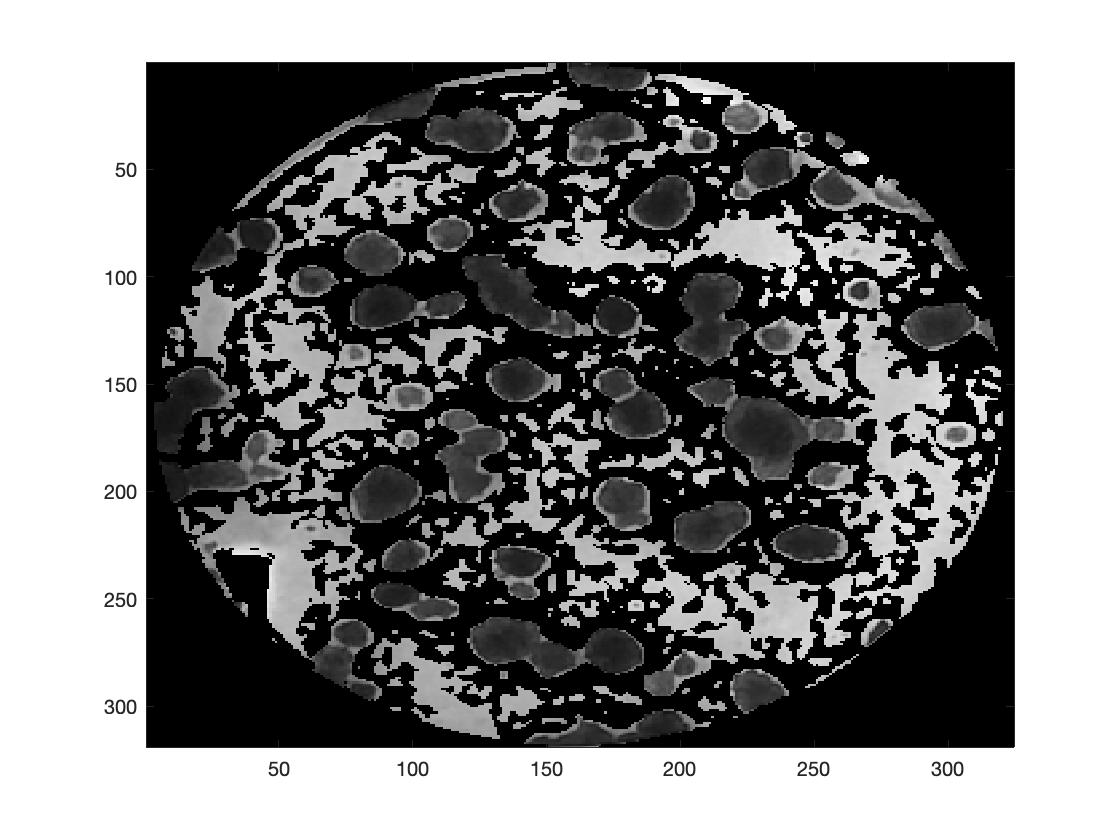

    figure
    imagesc(blurryImage), colormap gray

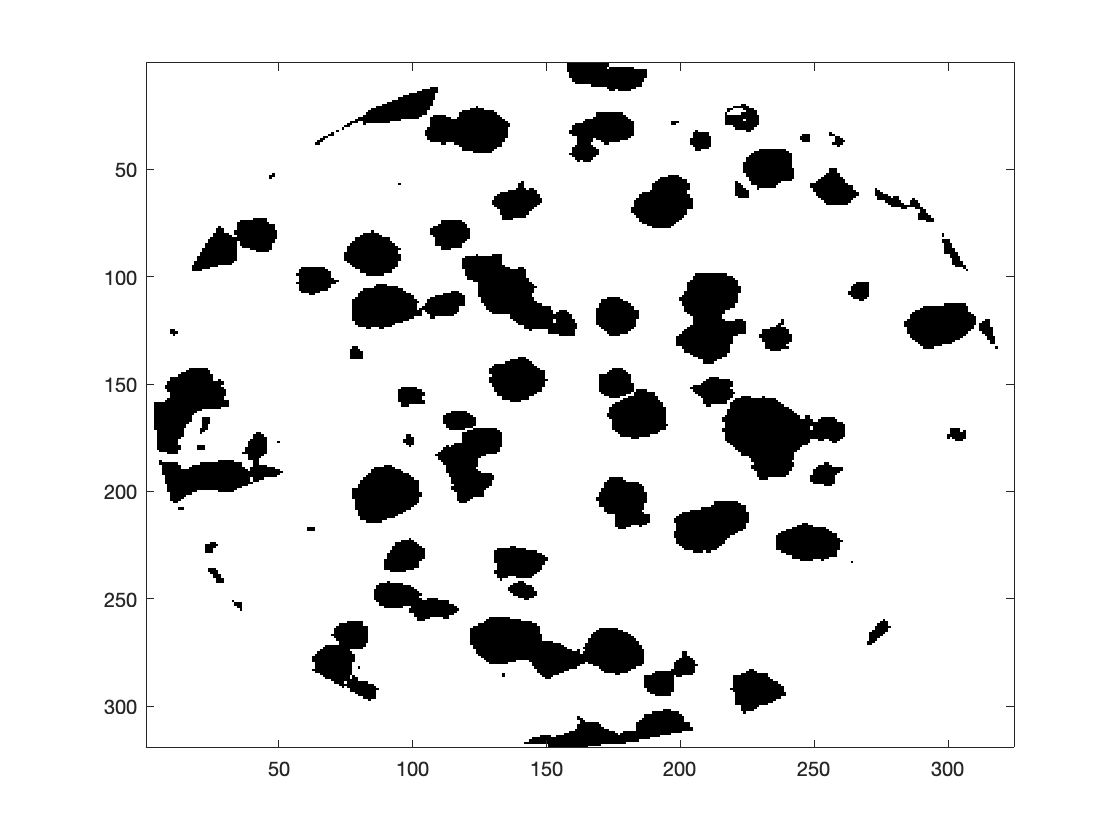

    blurryBinary = ~blurryImage; %Binary image where white = blurry regions
    
   brightnessThreshold =90; % Example threshold value that the cells have to be darker than to count as foreground
    
    % Create a binary mask for regions above the brightness threshold
    aboveThresholdMask = img_blurred > brightnessThreshold;
    
    % Set the corresponding regions in 'back' to white
    blurryBinary(aboveThresholdMask) = 1;
    figure, imagesc(blurryBinary), colormap gray

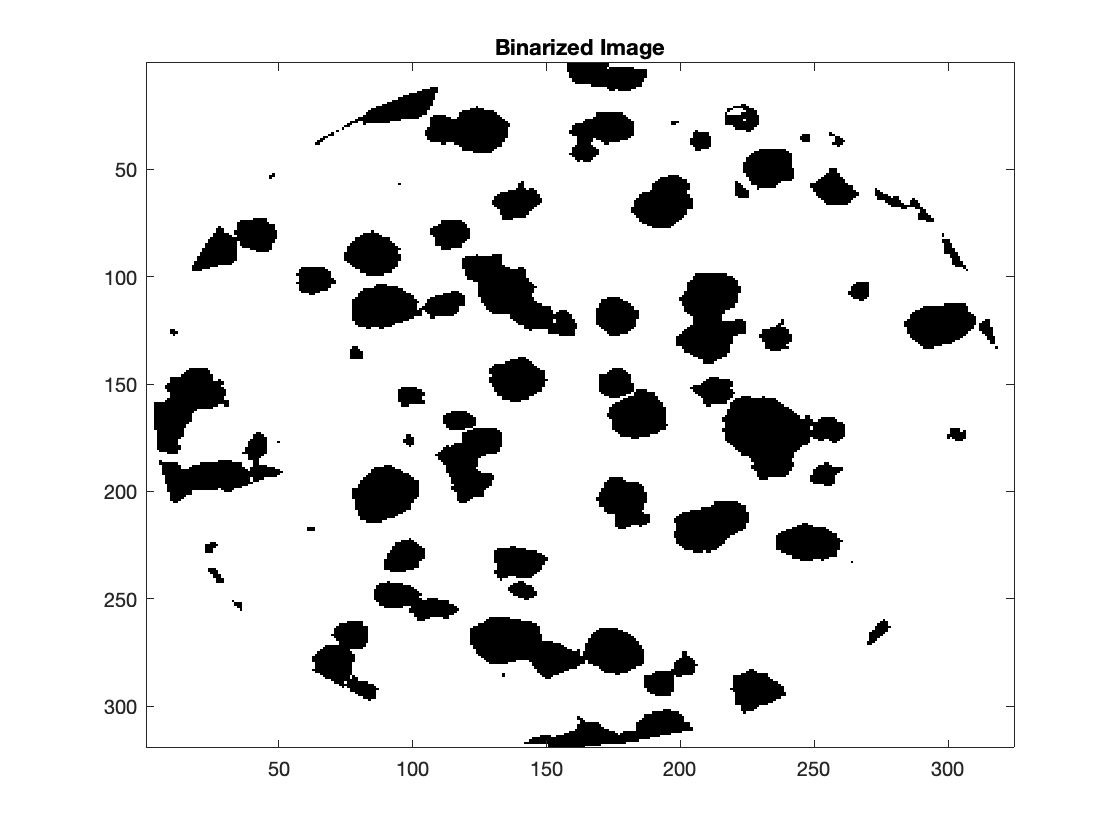

    

    % Apply a threshold to separate foreground and background
    [thresholded, sensitivity] = adaptiveThreshold(img_blurred); 

    thresholded(blurryBinary) = 1;
    bw = thresholded;

     figure

    colormap gray
    imagesc(bw),  title('Binarized Image')  

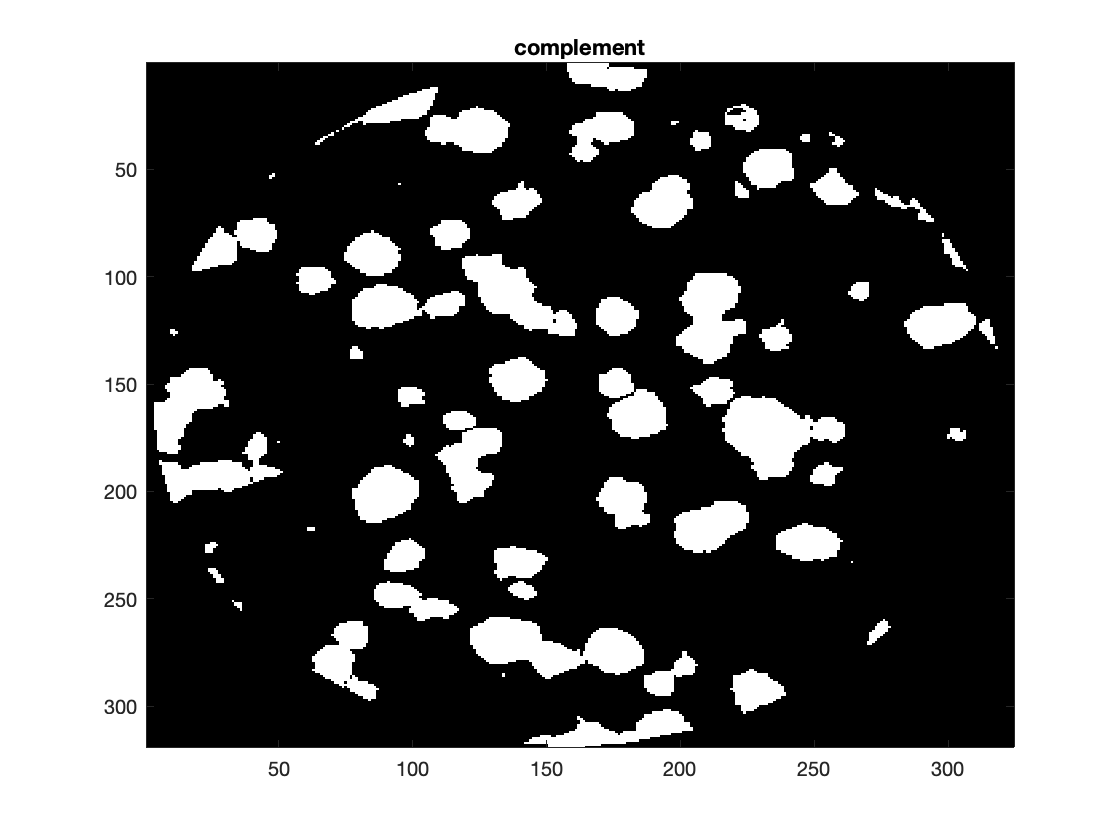

%create complement & get rid of small specs
bw2 = ~bw;
imagesc(bw2), title('complement')

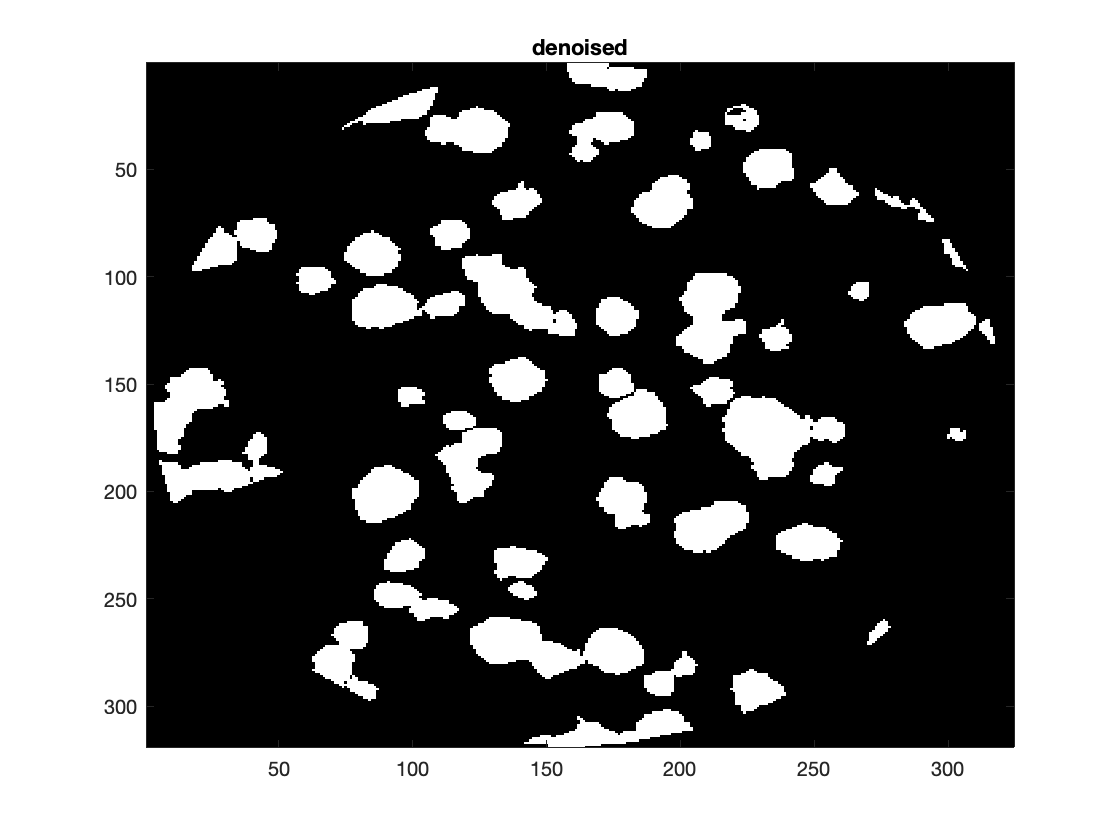

denoised = bwareaopen(bw2, 30);
figure, imagesc(denoised), title('denoised'), colormap gray

not necessary for `"7860_Fluva1.25+VHLa.jpeg"`

% %dilation/erosion to solidify cell parts & get rid of noise
% se = strel('disk', 5);
% dilated = imdilate(denoised, se);
% figure
% imshow(dilated)
% eroded = imerode(dilated, se);
% imshow(eroded)
% cleaned1 = bwareaopen(eroded, 1000); %get rid of white noise
% cleaned2 = ~bwareaopen(~cleaned1, 1000); %fill in small black holes
% imshow(cleaned2)
cleaned2 = denoised;

% Perform connected component analysis and obtain region properties
props = regionprops(cleaned2, 'Area');

% Extract the areas of all objects
areas = [props.Area];

% Sort the areas in ascending order
sortedAreas = sort(areas);

% Display the sorted sizes of all objects
disp(sortedAreas(:));

    54
    66
    67
    91
   108
   150
   181
   313
   315



Finding out the colony count -- change the avg colony pixel size as needed by photo batch

- changed threshold for objects considered a single cell to **344**

- changed it to **330** for avg size fluva batch

areas = sortedAreas(:);

% Determine the threshold area for dividing objects
thresholdArea = 344;

% Count the number of objects
numObjects = numel(props);

% Initialize the rounded count variable
roundedCount = 0;

% Iterate through each object
for i = 1:numObjects
    % Check if the object is larger than the threshold
    if areas(i) > thresholdArea
        % Divide the area by the threshold and round to the nearest integer
        roundedCount = roundedCount + round(areas(i) / 330); %dividng conjoined areas by avg colony size
    else
        % Increment the count for smaller objects
        roundedCount = roundedCount + 1;
    end
end

% Display the final count
disp(roundedCount);

     9



tableName = "clonogenic"+'.xls'; %excel file where you want to store analysis stats

%store final img & data
C = imfuse(cleaned2,img_blurred,'montage');
%imshow(C)

S = extractBefore(imgTitle, '.jpeg');
fileName = "MONTAGE " + S + '.jpeg';
imwrite(C,fileName)

if ~isfile(tableName) %if the table does not already exist
    colNames = {'Photo Name', 'colonies'};
    data = cell(1,2); % create a cell array with one row and the same number of columns as colNames
    table = [cell2table(colNames, 'VariableNames', colNames); cell2table(data, 'VariableNames', colNames)]
    writetable(table, tableName);
    existingTable = readtable(tableName);
    existingTable(1,:) = []; %remove duplicate column names row
else
    existingTable = readtable(tableName); %no need to remove duplicate col name row in this case
end

fprintf('This table is stored as %s in %s:', tableName, filePath)

This table is stored as clonogenic.xls in /Users/elizabeth 1/Desktop/Wu Lab/6. clonogenic assay by EB copy/subimages retaken/:


newRow = {imgTitle, roundedCount}; 


data = [existingTable;newRow]; %add data from analysis
% Find the unique values in PhotoName column
[~, ia, ~] = unique(flipud(data.PhotoName),'rows', 'stable');
ia = size(data,1) - ia + 1;% Select only the rows that contain unique values. If you ran code for
% the same image >1 time, the program will save the most recent version of
analysisStats = flipud(data(ia, :))

analysisStats = 49×2 table
             PhotoName              colonies
    ____________________________    ________

    "7860_Atorva_1.25+VHLa.jpeg"      147   
    "7860_Atorva_1.25+VHLb.jpeg"      131   
    "7860_Atorva_1.25c.jpeg"          127   
    "7860_Atorva_1.25d.jpeg"          149   
    "7860_Atorva_10+VHLa.jpeg"         72   
    "7860_Atorva_10+VHLb.jpeg"         78   
    "7860_Atorva_10c.jpeg"             73   
    "7860_Atorva_10d.jpeg"             59   
    "7860_Atorva_2.5+VHLa.jpeg"       128   
    "7860_Atorva_2.5+VHLb.jpeg"       123   
    "7860_Atorva_2.5c.jpeg"           122   
    "7860_Atorva_2.5d.jpeg"           110   
    "7860_Atorva_5+VHLa.jpeg"         140   
    "7860_Atorva_5+VHLb.jpeg"         128   
    "7860_Atorva_5c.jpeg"             114   
    "7860_Atorva_5d.jpeg"              50   



writetable(analysisStats, tableName, 'WriteMode', 'overwrite'); %add data to table

displaying images to see dimensions

*found out that dimensions of all fluva images are the same*

fileList = dir(fullfile(filePath, '*.jpeg'));  % List all PNG files (modify the extension as needed)
% Extract the filenames from the structure
filenames = {fileList.name};

filenames = 1×9 cell array
    {'7860_Fluva1.25+VHLa.jpeg'}    {'7860_Fluva1.25+VHLb.jpeg'}    {'7860_Fluva1.25c.jpeg'}    {'7860_Fluva1.25d.jpeg'}    {'7860_Fluva2.5+VHLa.jpeg'}    {'7860_Fluva2.5+VHLb.jpeg'}    {'7860_Fluva2.5c.jpeg'}    {'7860_Fluva5+VHLa.jpeg'}    {'7860_Fluva5+VHLb.jpeg'}


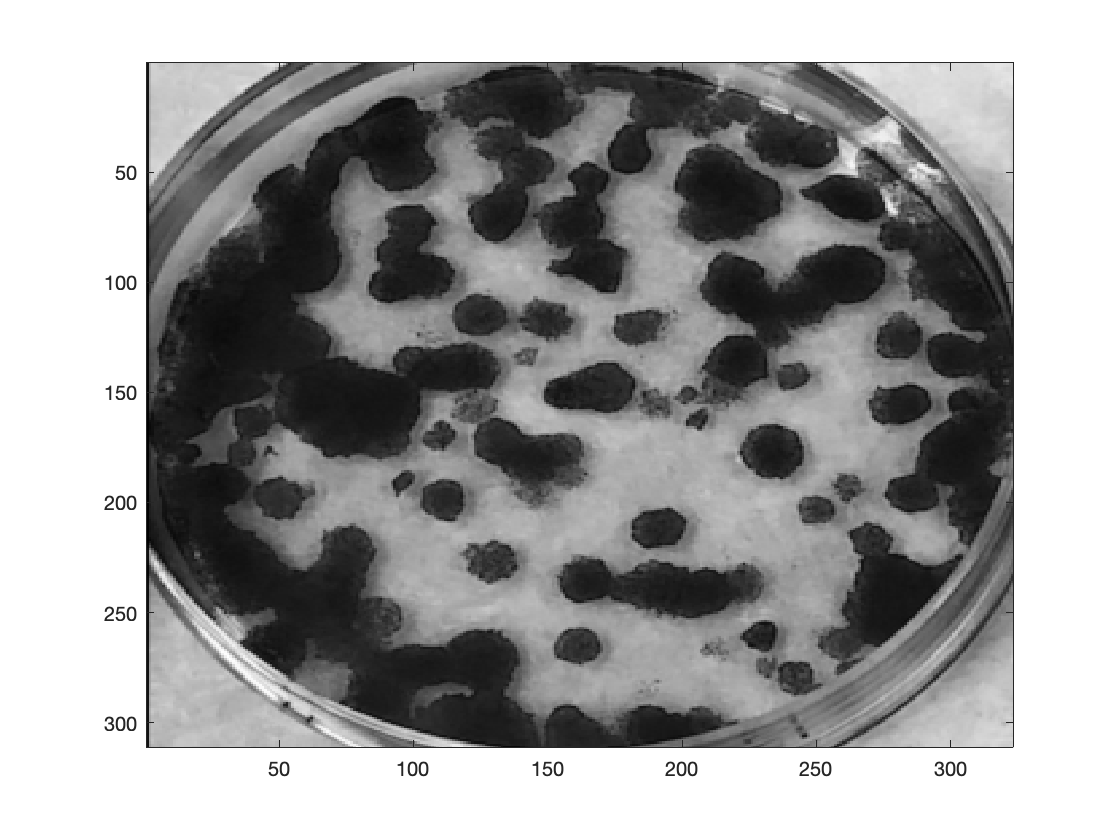

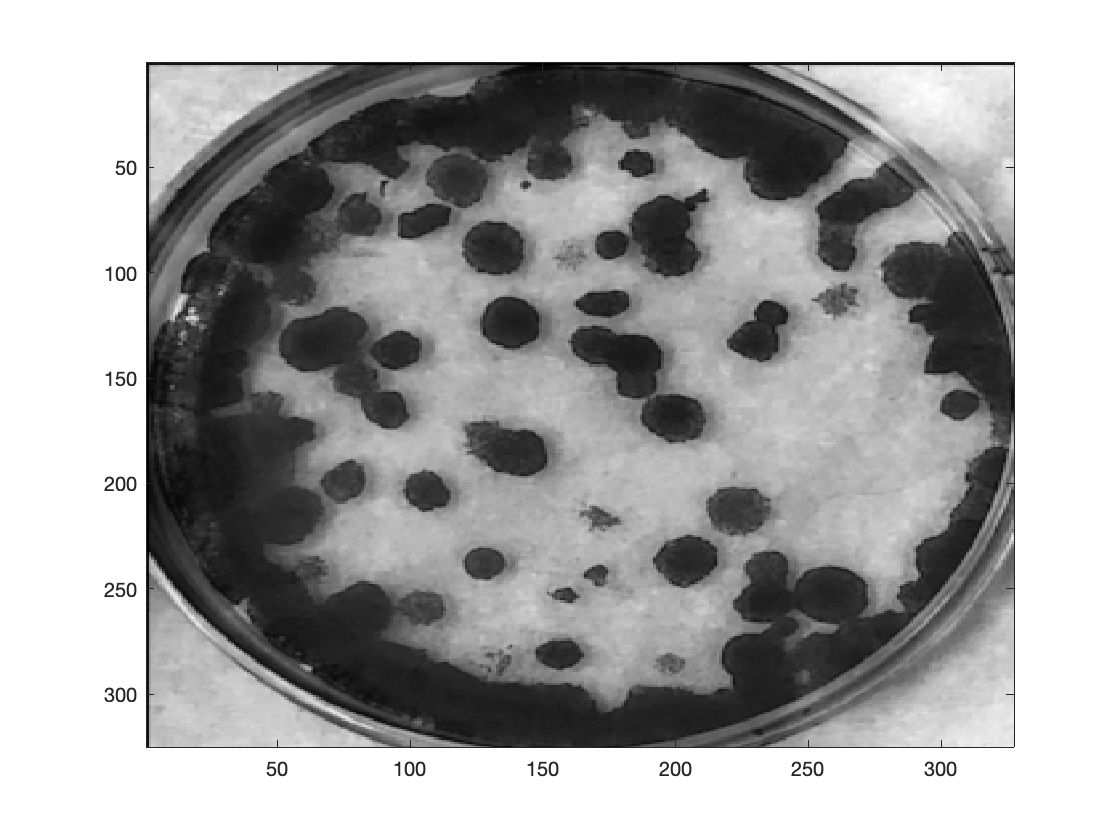

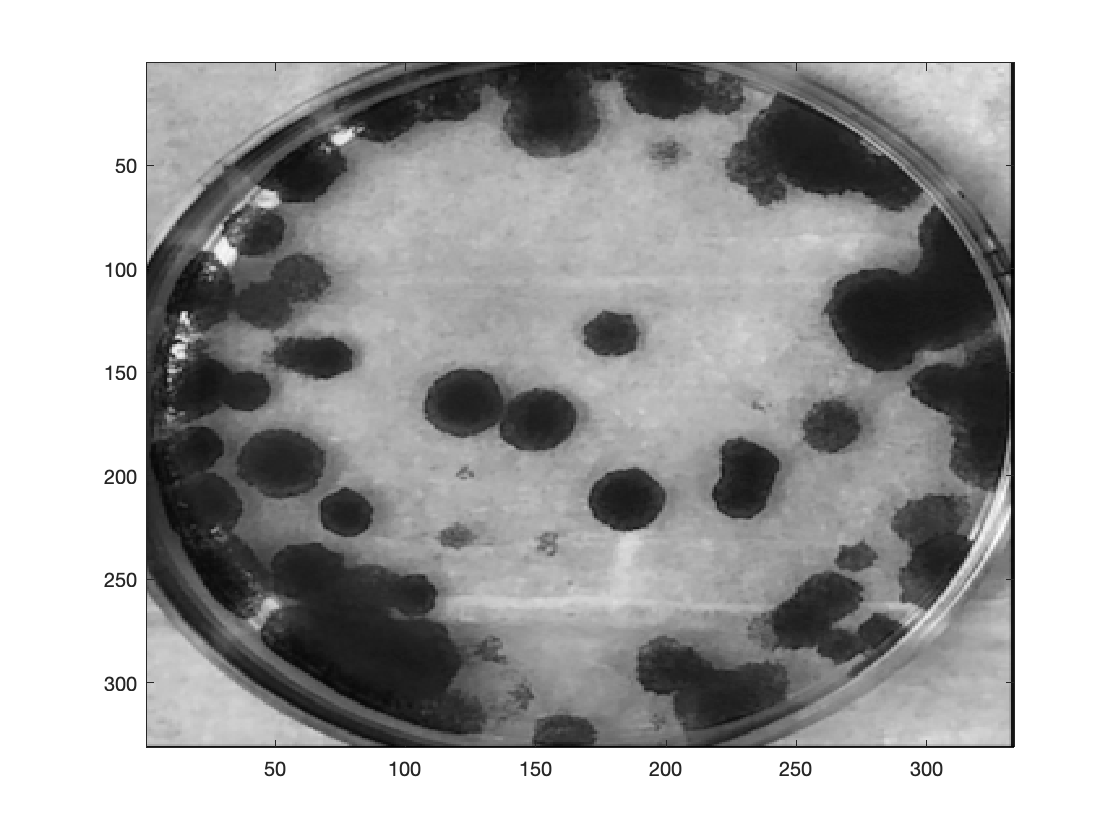

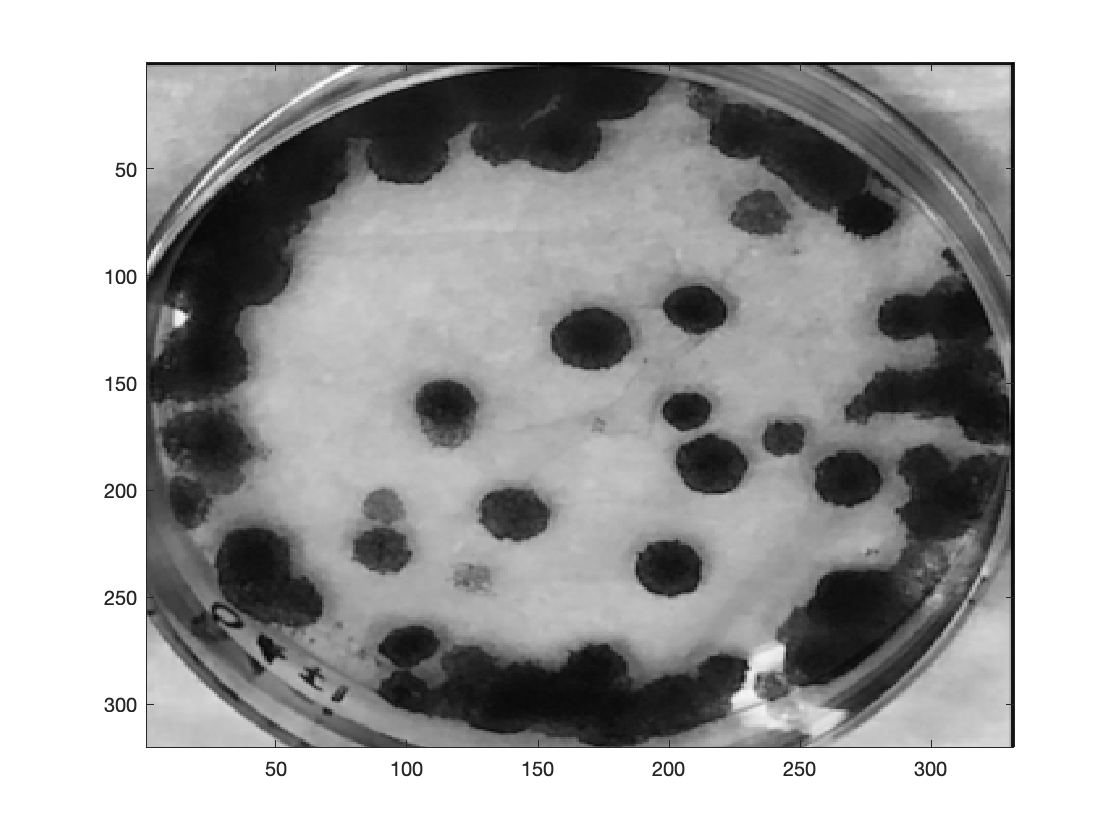

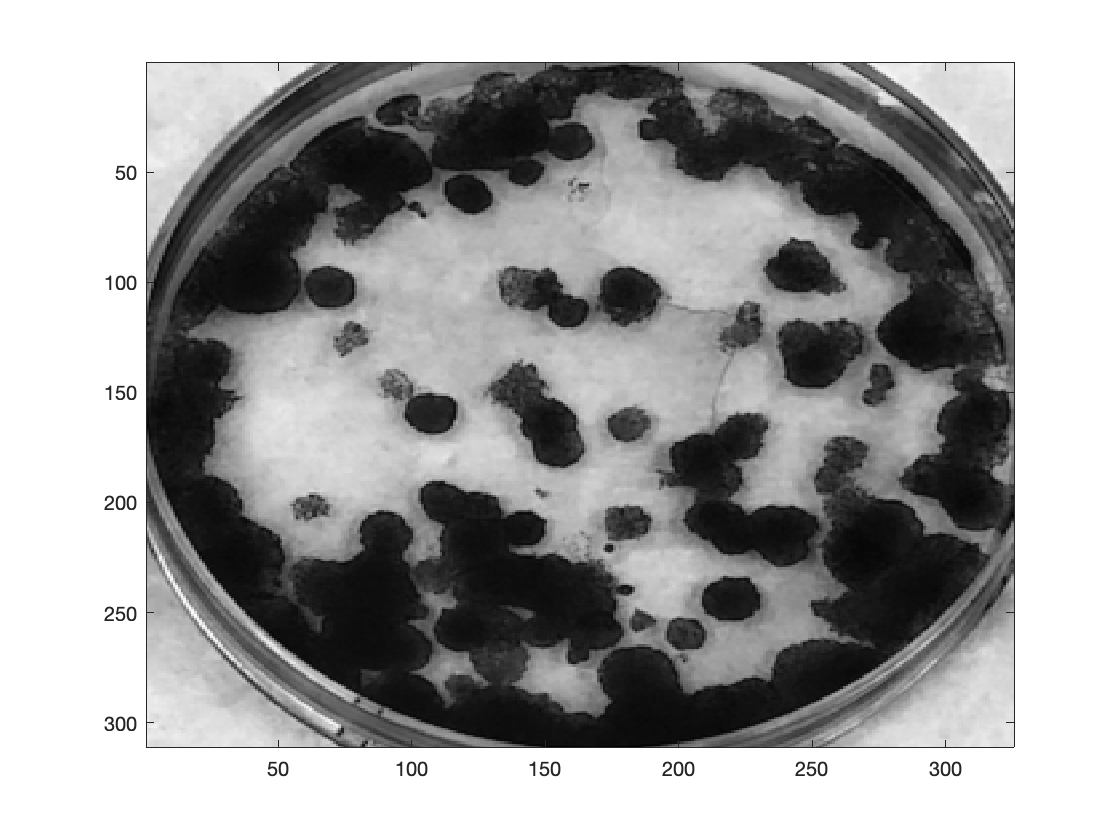

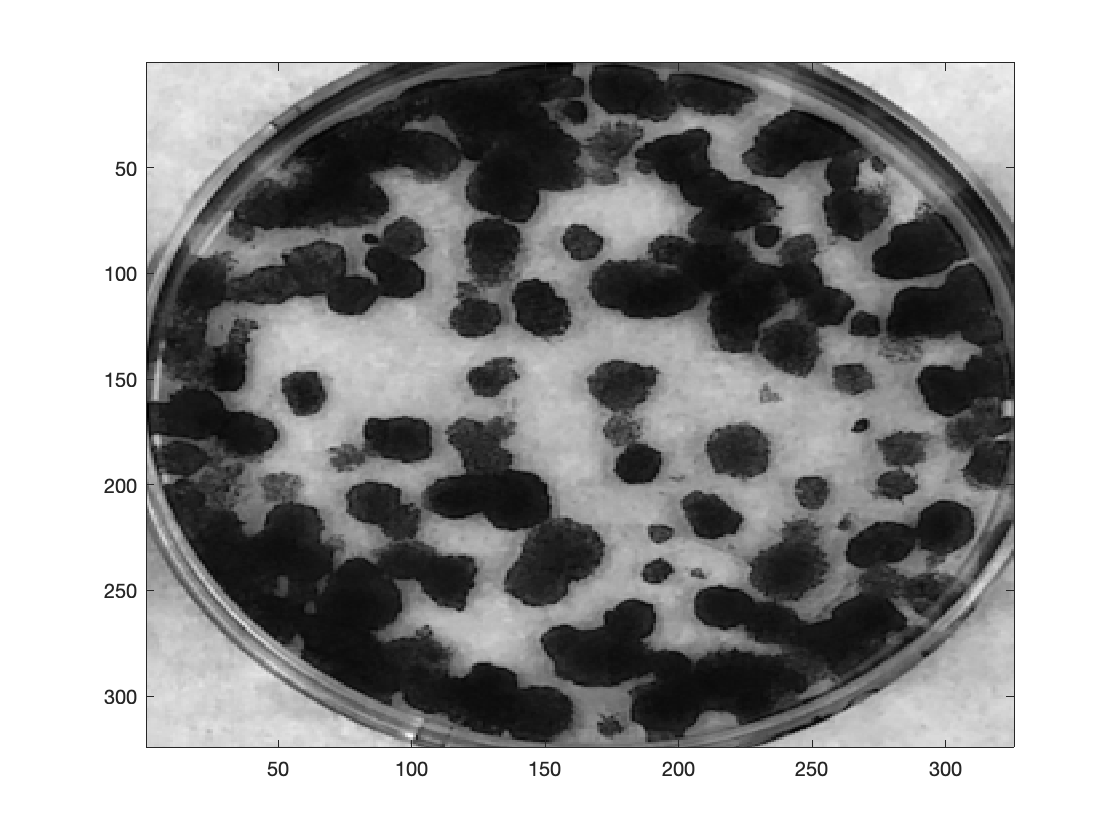

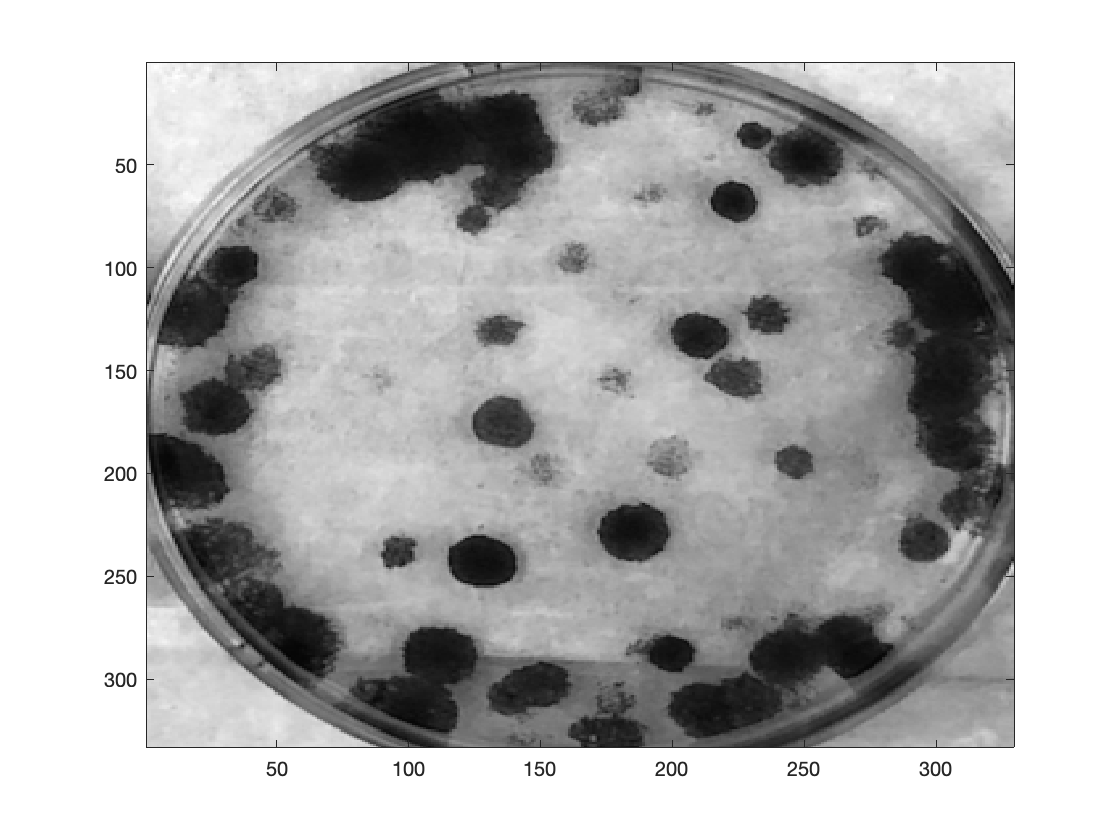

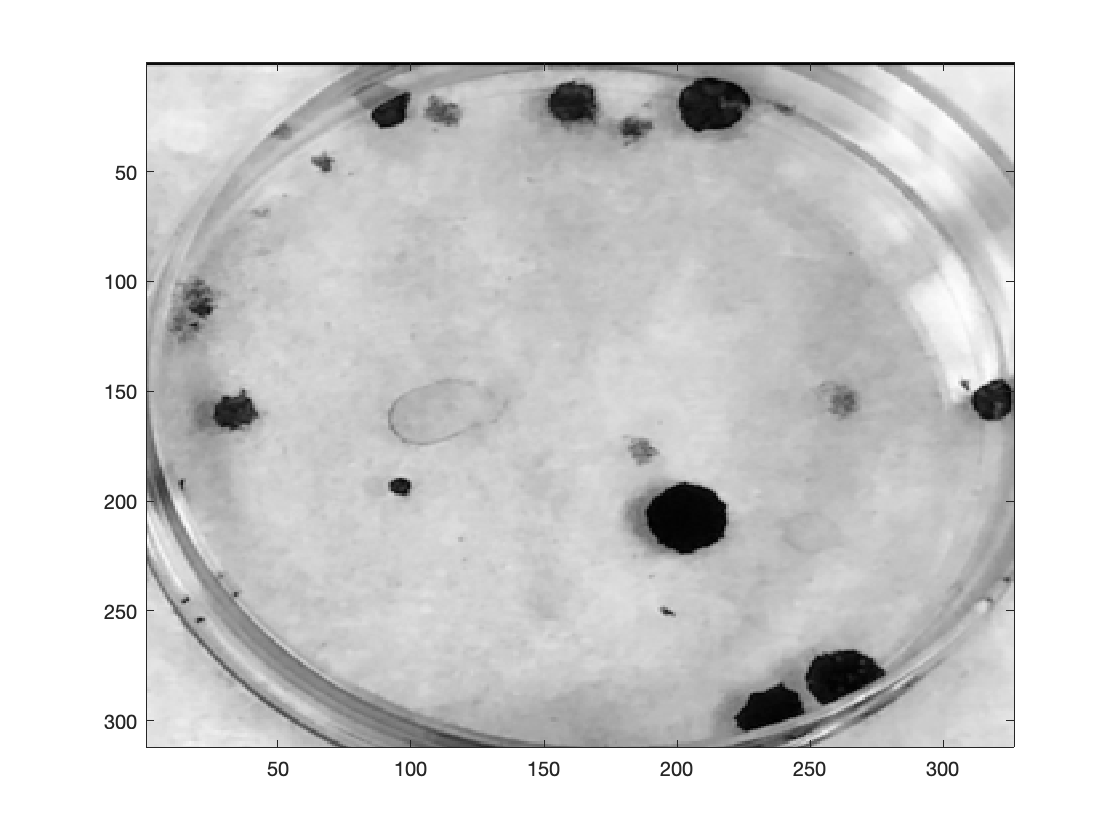


for i = 1:length(filenames)
    imgTitle = string(filenames(i));
    img1 = imread(imgTitle); %read in image
    img = rgb2gray(img1); %convert to grayscale
    img_blurred = imgaussfilt(img);
    figure
    imagesc(img_blurred), colormap gray
end

finding out the size of an average cell with this photo dimension

*found out that it's ~400 for the first fluva image*

*threshold 424 for dividing object (if it's >424 pixels, it's considered a conjoined colony)*

disp(sortedAreas(:))

          51
          56
          60
          62
          69
          81
          83
          83
          84
          85
          94
         115
         125
         159
         164
         168
         170
         181
         186
         193
         209
         229
         232
         244
         246
         265
         288
         289
         305
         322
         327
         343
         345
         355
         380
         386
         455
         460
         479
         566
         582
         669
         722
         777
         830
         909
        1058
        1158
        1221
        1338
        1357



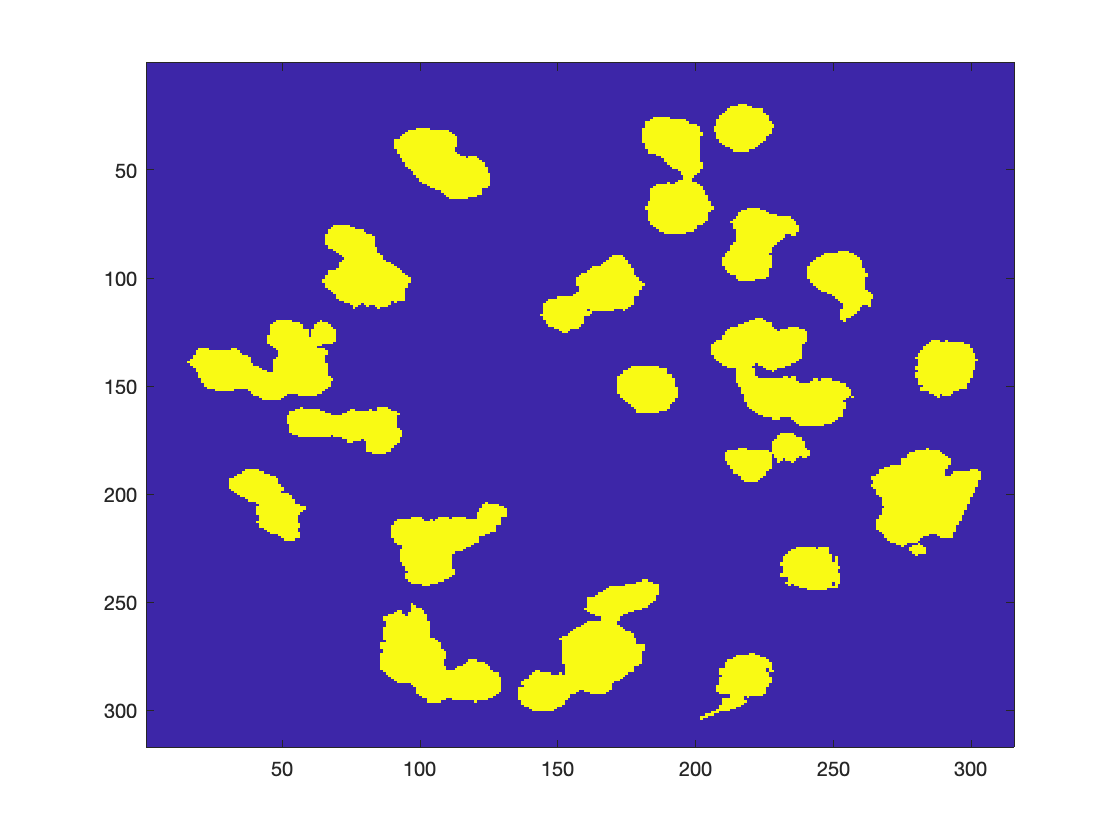

size_check = bwareaopen(denoised,330);
imagesc(size_check)